# **FIND THE COORDINATES OF ALL THE SLITS PIXELS**

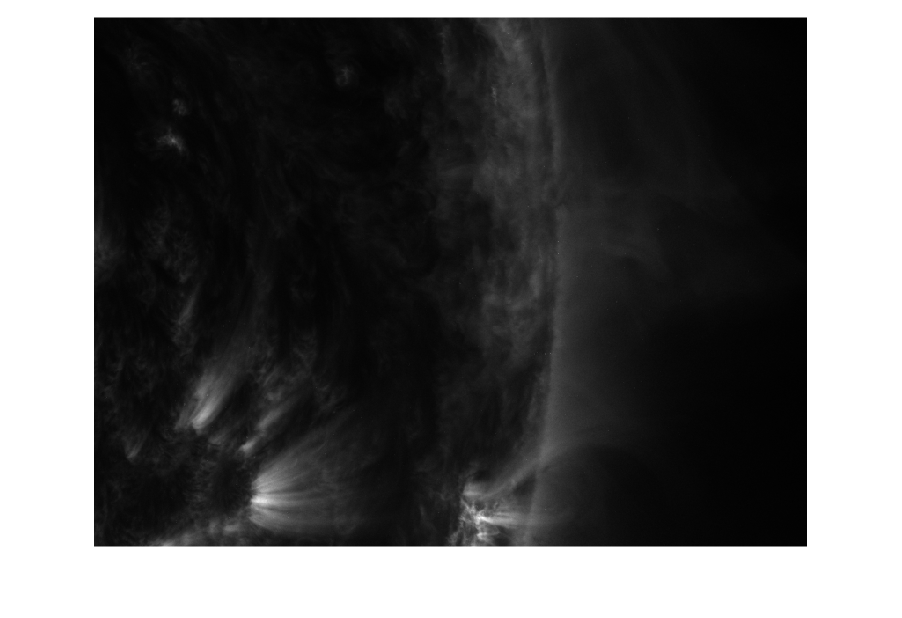

clear
close all

date = '2023_07_19';
loop_number = '01';

cd(['/Users/nechaeva/Documents/AIA_data/' date '_AIA_171' '/loop' loop_number])
load("sl_coord.mat")
cd(['/Users/nechaeva/Documents/AIA_data/' date '_AIA_171'])    % path to .fits files

% as in the previous script update this for your path

dirfiles = dir;
dirfiles(1:2) = [];

for i = 1:size(dirfiles,1)
if (dirfiles(i).name(end-4:end) == '.fits' )
    dirmat(i,1).name = dirfiles(i).name;
else
    dirmat(i,1).name = [];
end
end
dirfiles = dirmat;

m = round(size(dirfiles,1)/2);

main_image_BW = fitsread(dirfiles(m).name,'image');
main_image_BW = uint8(main_image_BW/max(main_image_BW,[],'all')*255);
     cd('/Users/nechaeva/Documents/MATLAB/oscillations_analysis')

imshow(main_image_BW)    % shows original image

      n_sl = size(sl_coord,3);    % number of slits
      slit_pixels_summary = NaN(500,2,n_sl);    % creates NaN array for the coordinates of the slit pixels
      % i use fixed size array if you use longer slits you may want to make
      % it bigger than 500 elemnts

      for j = 1:n_sl
          sl_coord1(1,1:4,j) = reshape(sl_coord(:,:,j),1,4);    % reshape for the bresenham function to read correctly
      end

      sl_coord = sl_coord1;
      for ii = 1:n_sl
        [xx yy] = bresenham(sl_coord(:,:,ii));    % here i use custom function https://www.mathworks.com/matlabcentral/fileexchange/28190-bresenham-optimized-for-matlab
        slit_pixels_summary(1:size(xx,1),1,ii) = xx;    % all the x coordinates
        slit_pixels_summary(1:size(yy,1),2,ii) = yy;    % all the y coordinates
        slit_pixels_summary(size(xx,1)+1:end,1,ii) = NaN;    % fill the rest of the unused elements with NaN 
        slit_pixels_summary(size(xx,1)+1:end,2,ii) = NaN;
      end
   
clear dirmat i m ii j sl_coord1 xx yy 
%cd(['/Users/nechaeva/Documents/AIA_data/' date '_AIA_171'])    % path to .fits files

**USE THIS ONLY IF YOU WANT TO CHECK THE RESULT OF THE ALGORITM**

### ***NOT NECESARRY***

% % % figure
% % % imshow(main_image_BW)
% % % 
% % % for n = 1:n_sl
% % %     pixels_n = slit_pixels_summary(:,:,n);
% % %     pixels_n(all(isnan(pixels_n),2),:) = [];    % remove NaNs
% % % 
% % %     for k = 1:size(pixels_n,1)
% % %         hold on
% % %         plot(pixels_n(k,1),pixels_n(k,2),'k.')
% % %     end
% % % end
% % % 
% % % for j = 1:n_sl
% % %     plot([sl_coord(1,1,j) sl_coord(1,3,j)],[sl_coord(1,2,j) sl_coord(1,4,j)],'*')
% % % end
% % % clear j k n pixels_n

**create td maps and save as images**

slit 1 is processing


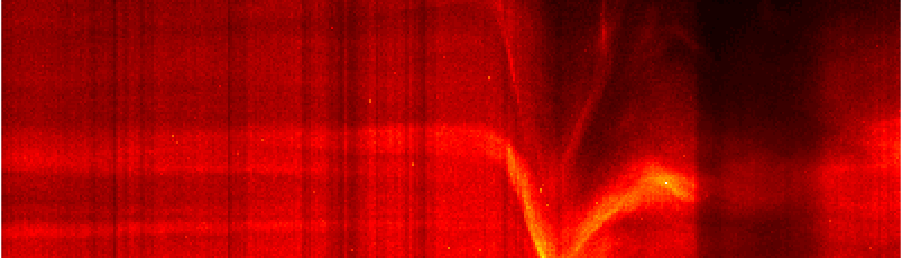

slit 2 is processing


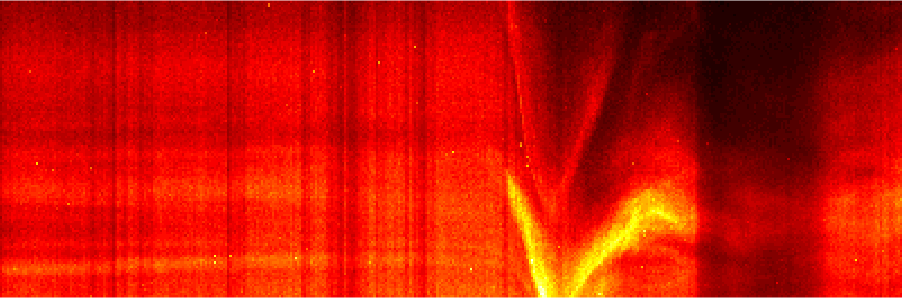

slit 3 is processing


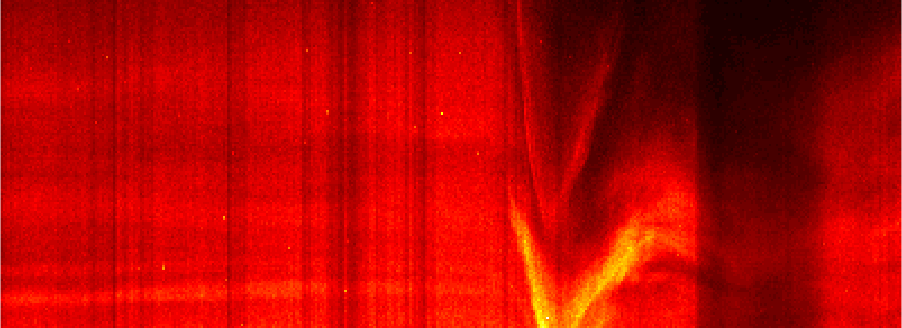

slit 4 is processing


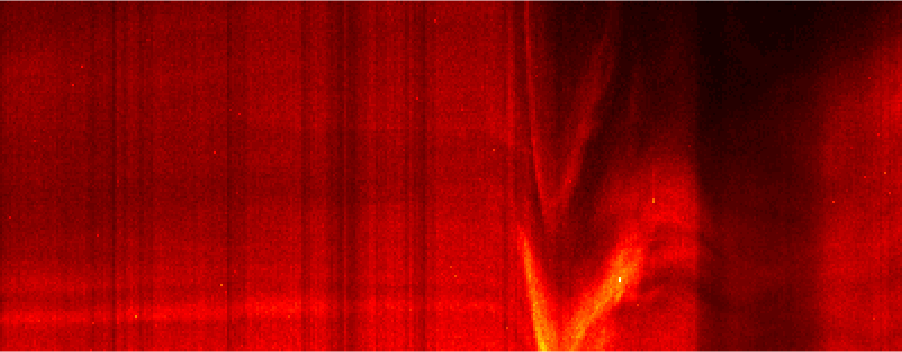

slit 5 is processing


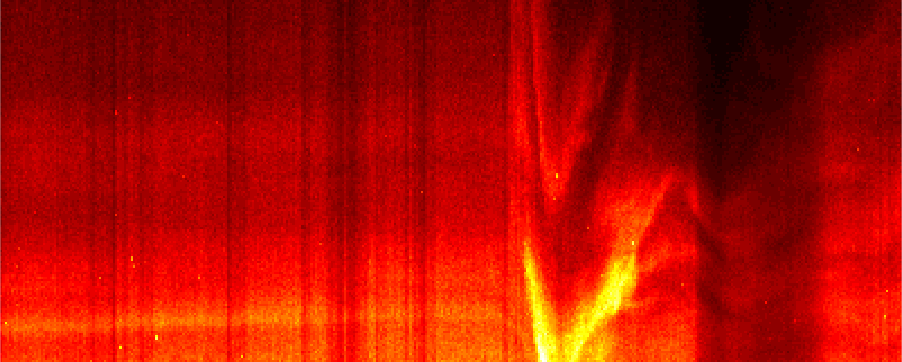

slit 6 is processing


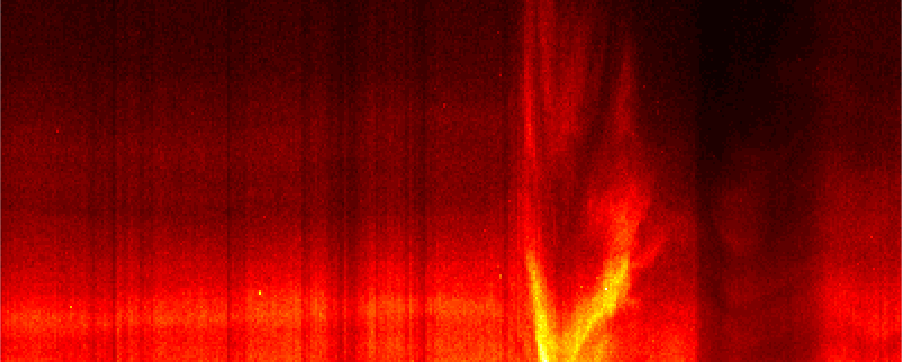

slit 7 is processing


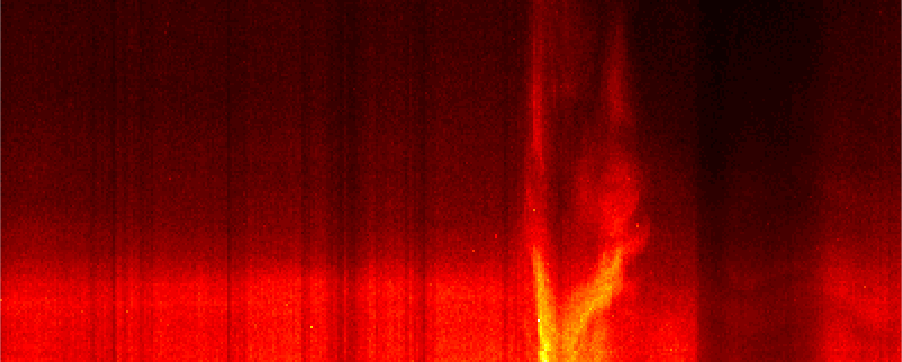

slit 8 is processing


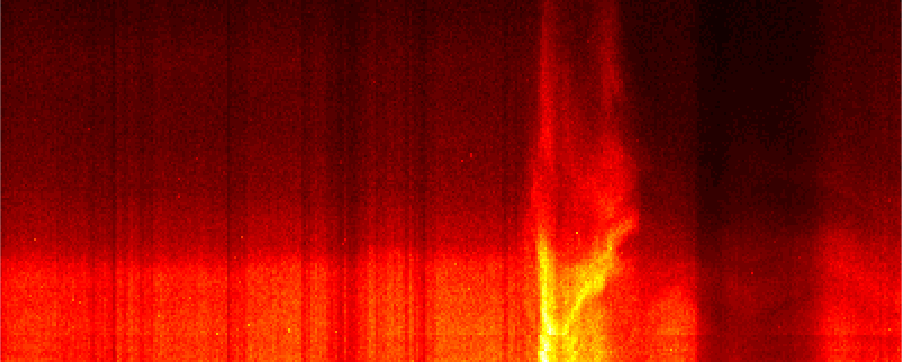

slit 9 is processing


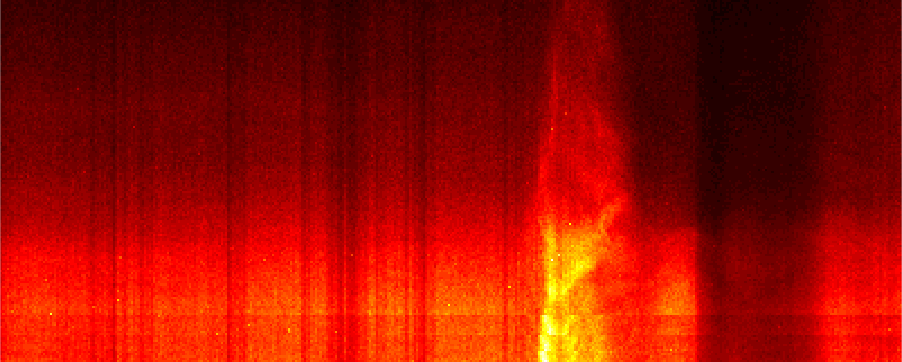

slit 10 is processing


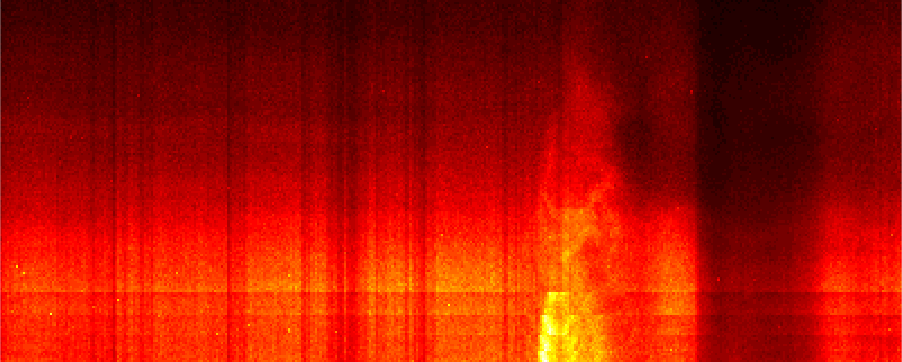

slit 11 is processing


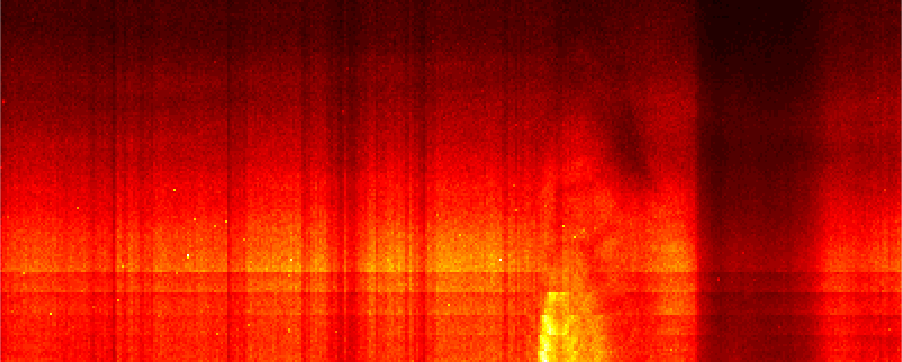

slit 12 is processing


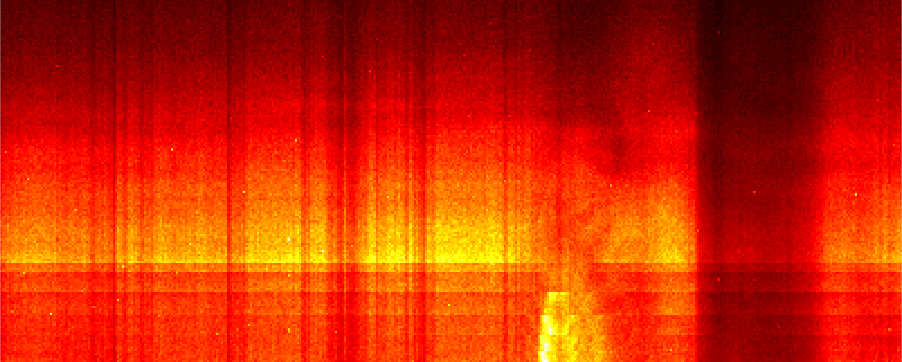

slit 13 is processing


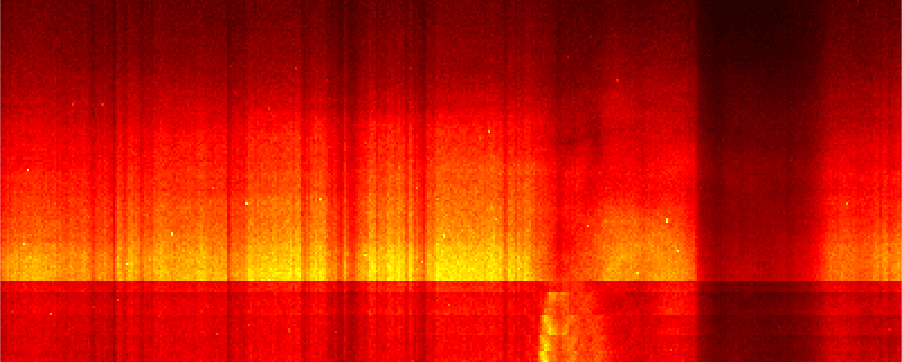

slit 14 is processing


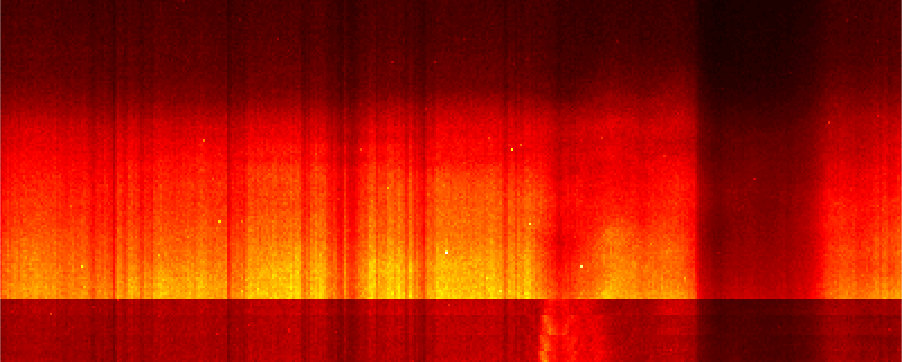

slit 15 is processing


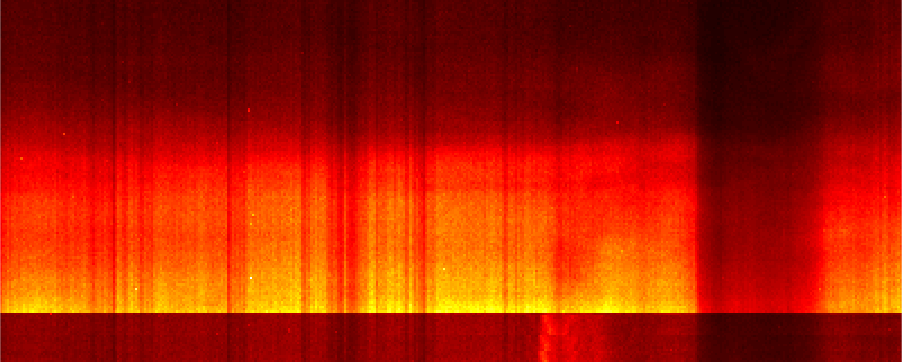

slit 16 is processing


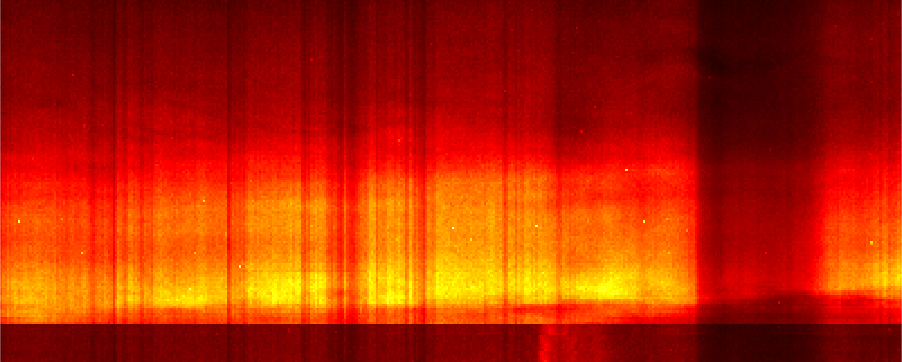

slit 17 is processing


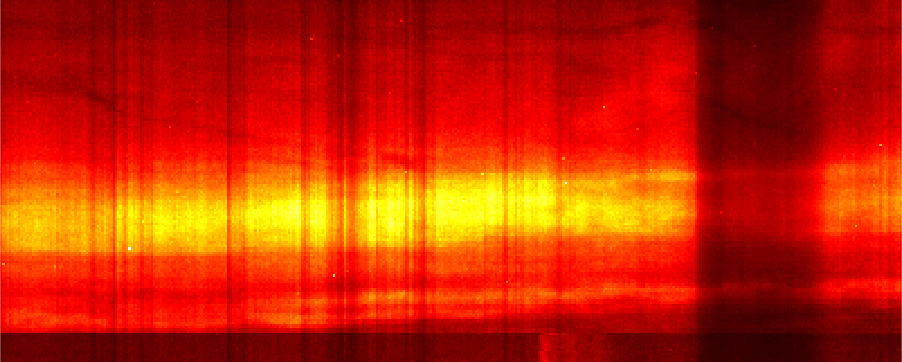

slit 18 is processing


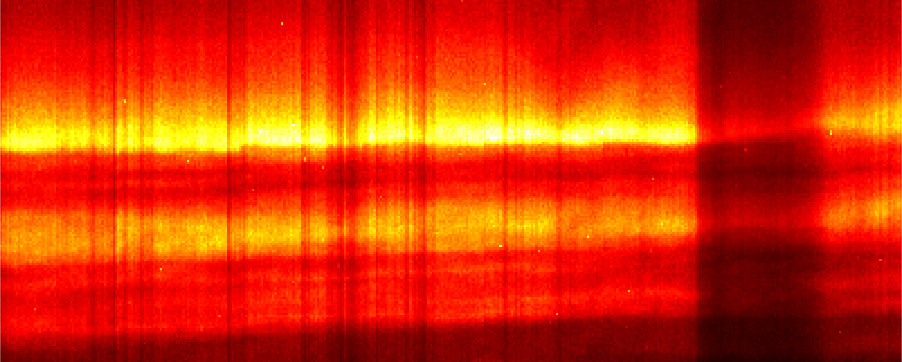

slit 19 is processing


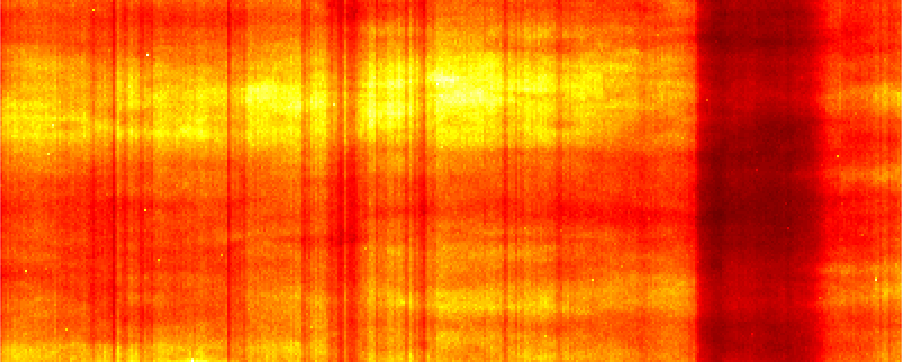

slit 20 is processing


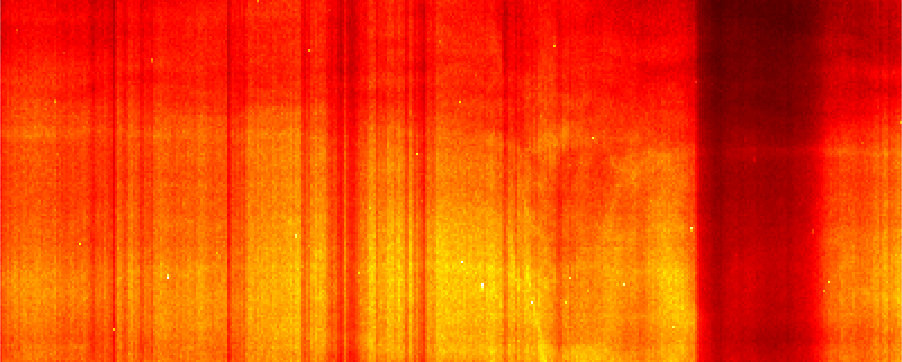

slit 21 is processing


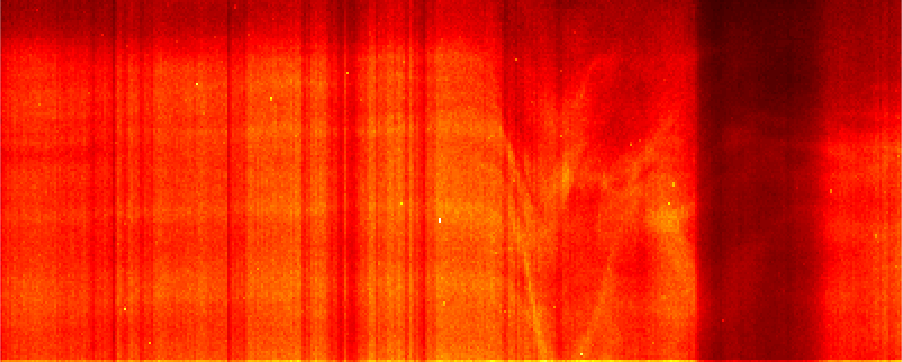

slit 22 is processing


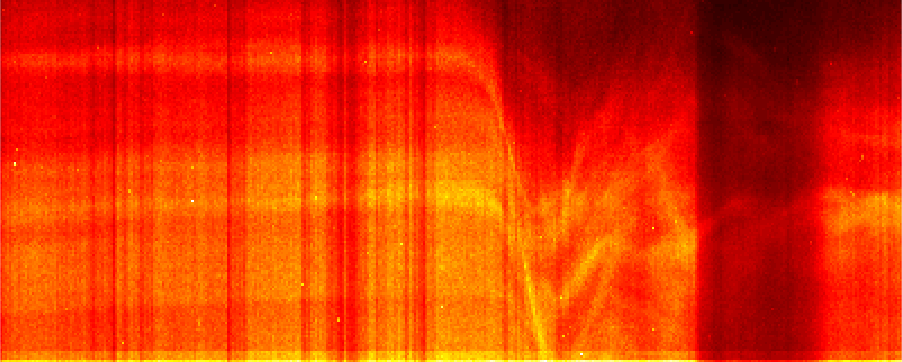

slit 23 is processing


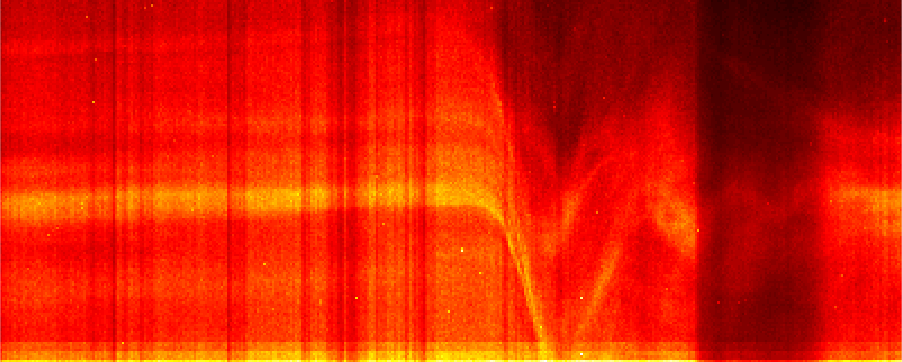

slit 24 is processing


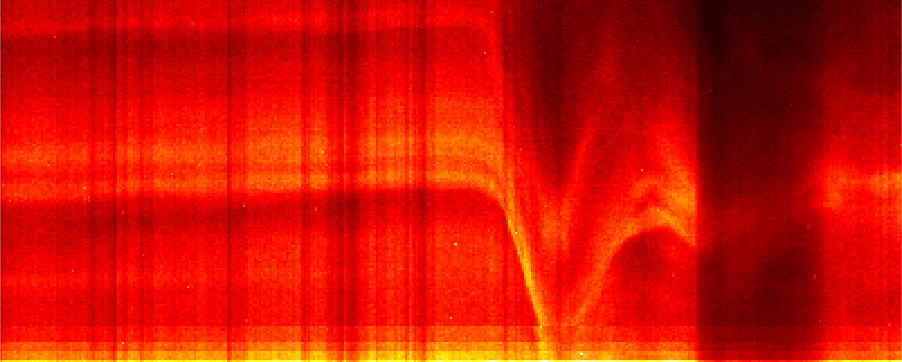

slit 25 is processing


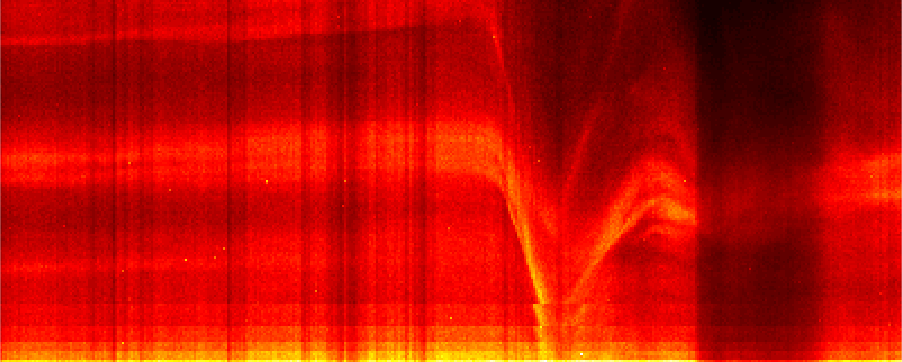

slit 26 is processing


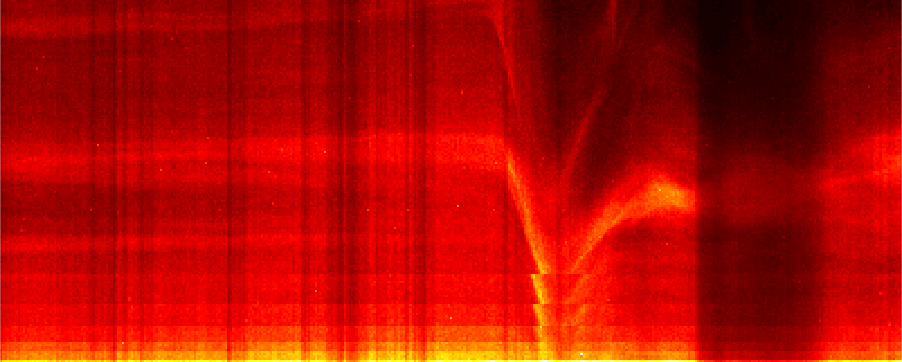

cd(['/Users/nechaeva/Documents/AIA_data/' date '_AIA_171'])    % your path
for n = 1:n_sl
   pixels_n = slit_pixels_summary(:,:,n);
   pixels_n(all(isnan(pixels_n),2),:) = [];    % remove NaNs
   disp(['slit ' num2str(n) ' is processing'])    % shows progress


    for pic = 1:size(dirfiles,1)-1
        main_image_BW = fitsread(dirfiles(pic).name,'image');
        main_image_BW = uint8(main_image_BW/max(main_image_BW,[],'all')*255);

         for px = 1:size(pixels_n,1)
            td_map(px,pic) = main_image_BW(pixels_n(px,2),pixels_n(px,1));    % creates td map
         end
    end

    clear px 

        cd(['/Users/nechaeva/Documents/AIA_data/' date '_AIA_171' '/loop' loop_number])

        figure
        imshow(td_map,[0 max(td_map,[],'all')]*0.95,'InitialMagnification',500, ...
            'Border','tight')
        shading flat
        colormap(hot)

        saveas(gcf,['td_map_slit_' num2str(n) '.png'])    % saves all the td maps as .png files
        cd(['/Users/nechaeva/Documents/AIA_data/' date '_AIA_171'])
        

end

clear n pic